close all;
clear; clc;
format compact;

links = [5; 5; 5; 5];
initalState = deg2rad([60; -120; 120; -120]);
robot = SerialLinkManipulator(links, initalState);

configuration = [pi/2, -pi/4, pi/4, -pi/4]';

% fv = robot.serialLinkPoly(cspace)
% 
% figure;
% 
% p = patch (fv);
% p.FaceColor = 'red';
% p.EdgeColor = 'none';
% 
% sz = 30;
% axis equal; grid on;
% axis (sz*[-1 1 -1 1]);

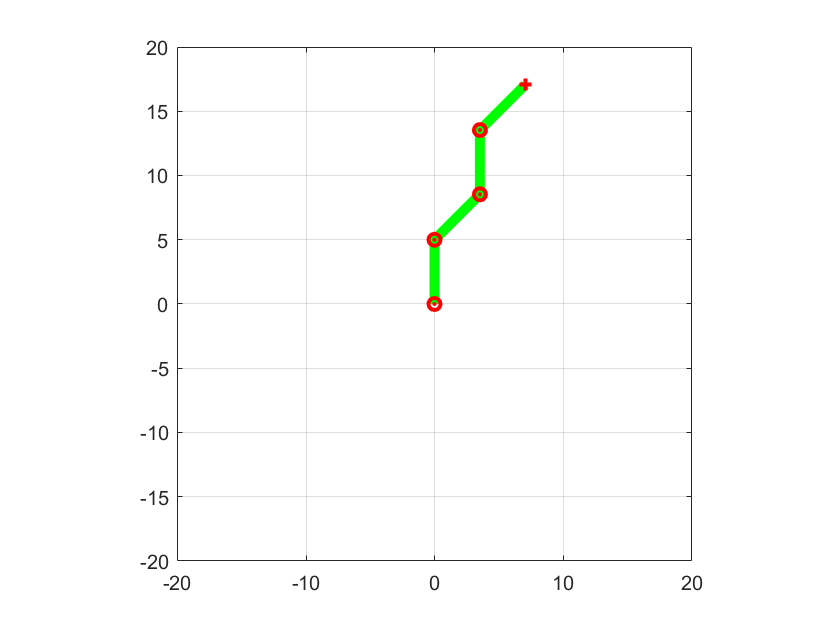

plotSize = 20;
joints = robot.taskSpace(configuration, plotSize);

% pos = [];
% for i = -pi/4:0.05:pi/4+0.1
%     pos = [pos, [pi/2 - i/2; -pi/4 + i/2; pi/4 + i; i]];
% end

% robot.drawConfiguration(pos);

% figure;
% plots = [];
% for i = pos
%     joints = robot.taskSpace(i, false);
% 
%     plot1 = plot(   joints(:, 1), joints(:, 2), ...
%             "LineWidth", 5, "LineStyle", '-', "Color", 'g'  );
%     hold on;
%     plot2 = plot(   joints(1:robot.nJoints, 1), joints(1:robot.nJoints, 2), ...
%             'or', "LineWidth", 2);
%     hold on;
%     plot3 = plot(   joints(end, 1), joints(end, 2), ...
%             '+r', "LineWidth", 2);
%     axis equal; grid on; axis (20*[-1 1 -1 1]);
% 
%     plots = [plot1 plot2 plot3];
%     pause(0.01);
%     delete(plots);
% end

alpha = -pi/16;
beta = pi/4;
gamma = -pi/2;

links = [0.5; 0.1; 0.5; 0.5];

% rotational matrices calculated in previous problem set
R_B1 = [    1,           0,           0;
            0,  cos(alpha), -sin(alpha);
            0,  sin(alpha),  cos(alpha)];

R_12 = [    cos(beta),   0,   sin(beta);
            0,           1,           0;
           -sin(beta),   0,   cos(beta)];

R_23 = [    cos(gamma),  0,   sin(gamma);
            0,           1,            0;
           -sin(gamma),  0,   cos(gamma)];



% links' lenght
lb = links(1);
l1 = links(2);
l2 = links(3);
l3 = links(4);

% write down the 3x1 relative position vectors for link length l_i=1
r_B1_inB = [0;  lb;  0];
r_12_in1 = [0;  0; -l1];
r_23_in2 = [0;  0; -l2];
r_3F_in3 = [0;  0; -l3];

% write down the homogeneous transformation matrices
H_B1 = [        R_B1,   r_B1_inB    ;
             0, 0, 0,          1    ];
H_12 = [        R_12,   r_12_in1    ;
             0, 0, 0,          1    ];
H_23 = [        R_23,   r_23_in2    ;
             0, 0, 0,          1    ];

% create the cumulative transformation matrix
H_B3 = H_B1 * H_12 * H_23;

co = [0; 0; 0];
cx = [1; 0; 0];
cy = [0; 1; 0];
cz = [0; 0; 1];

clen = 0.1;

O1 = H_B1*[co; 1];
O1 = O1(1:3);

X1 = H_B1*[clen*cx; 1];
X1 = X1(1:3);

Y1 = H_B1*[clen*cy; 1];
Y1 = Y1(1:3);

Z1 = H_B1*[clen*cz; 1];
Z1 = Z1(1:3);

O2 = H_B1*H_12*[co; 1];
O2 = O2(1:3);

X2 = H_B1*H_12*[clen*cx; 1];
X2 = X2(1:3);

Y2 = H_B1*H_12*[clen*cy; 1];
Y2 = Y2(1:3);

Z2 = H_B1*H_12*[clen*cz; 1];
Z2 = Z2(1:3);

O3 = H_B1*H_12*H_23*[co; 1];
O3 = O3(1:3);

X3 = H_B1*H_12*H_23*[clen*cx; 1];
X3 = X3(1:3);

Y3 = H_B1*H_12*H_23*[clen*cy; 1];
Y3 = Y3(1:3);

Z3 = H_B1*H_12*H_23*[clen*cz; 1];
Z3 = Z3(1:3);

leg = roboticLeg(links, -pi/16, pi/4, -pi/2);

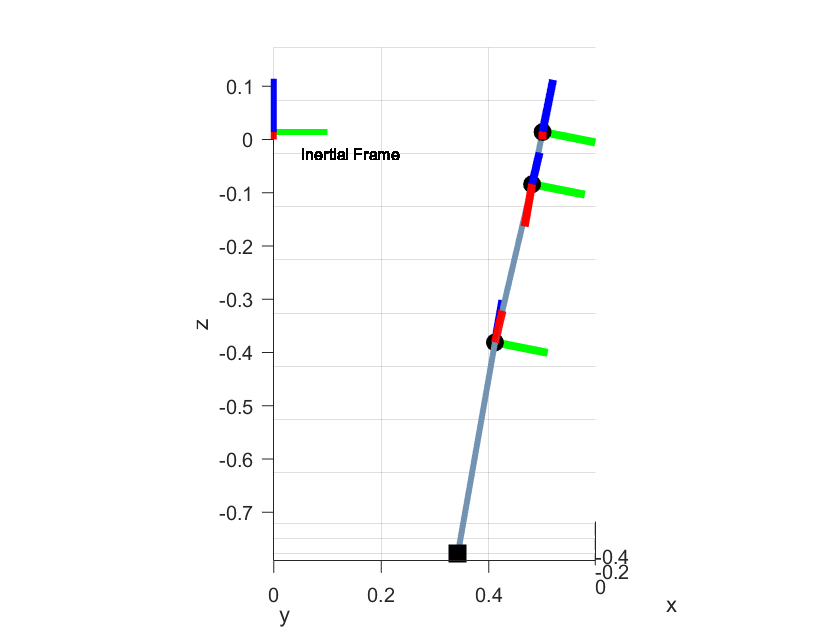

sz = 1.5;
figure;

% axis equal; grid on;
% xlabel('x'); ylabel('y'); zlabel('z');
% xlim(sz*[-1 +1]); ylim(sz*[0 +1]); zlim(sz*[-1 +1]); 

% figure;
for i = -90:90
    plot3(leg(1,:), leg(2,:), leg(3,:), "-", LineWidth=3, Color="#7393B3");
    hold on;
    plot3(leg(1,1:3), leg(2,1:3), leg(3,1:3), "o", LineWidth=3, Color='black');
    hold on;
    plot3(leg(1,4), leg(2,4), leg(3,4), "square", LineWidth=5, Color='black');
    
    hold on;
    
    plot3([co(1), clen*cx(1)], [co(2), clen*cx(2)], [co(3), clen*cx(3)], LineWidth=3, Color='red');
    hold on;
    plot3([co(1), clen*cy(1)], [co(2), clen*cy(2)], [co(3), clen*cy(3)], LineWidth=3, Color='green');
    hold on;
    plot3([co(1), clen*cz(1)], [co(2), clen*cz(2)], [co(3), clen*cz(3)], LineWidth=3, Color='blue');
    
    hold on;
    
    plot3([O1(1), X1(1)], [O1(2), X1(2)], [O1(3), X1(3)], LineWidth=4, Color='red');
    hold on;
    plot3([O1(1), Y1(1)], [O1(2), Y1(2)], [O1(3), Y1(3)], LineWidth=4, Color='green');
    hold on;
    plot3([O1(1), Z1(1)], [O1(2), Z1(2)], [O1(3), Z1(3)], LineWidth=4, Color='blue');
    
    hold on;
    
    plot3([O2(1), X2(1)], [O2(2), X2(2)], [O2(3), X2(3)], LineWidth=4, Color='red');
    hold on;
    plot3([O2(1), Y2(1)], [O2(2), Y2(2)], [O2(3), Y2(3)], LineWidth=4, Color='green');
    hold on;
    plot3([O2(1), Z2(1)], [O2(2), Z2(2)], [O2(3), Z2(3)], LineWidth=4, Color='blue');
    
    hold on;
    
    plot3([O3(1), X3(1)], [O3(2), X3(2)], [O3(3), X3(3)], LineWidth=4, Color='red');
    hold on;
    plot3([O3(1), Y3(1)], [O3(2), Y3(2)], [O3(3), Y3(3)], LineWidth=4, Color='green');
    hold on;
    plot3([O3(1), Z3(1)], [O3(2), Z3(2)], [O3(3), Z3(3)], LineWidth=4, Color='blue');
    
    text(-0.075, 0.05, -0.05, "Inertial Frame", "FontSize", 8);
    axis equal; grid on; view([i 8]);
    xlabel('x'); ylabel('y'); zlabel('z');

    pause(0.01);
end

% view([-90 90]);
% view([-90 0]);
% view([0 0]);